A = [-5 9;4 -7];

% compute the determinant of A
det_A = det(A)

det_A = -1.0000


% compute the inverse of A
inv_A = inv(A)

inv_A =     7.0000    9.0000
    4.0000    5.0000



% Define the matrix B
B = [2 1 3; 1 0 2; 3 2 1]

B =      2     1     3
     1     0     2
     3     2     1




% Compute the matrix of cofactors of A
[m, n] = size(B);
C = zeros(m,n);
for i = 1:m
    for j = 1:n
        D = B;
        D(i,:) = [];
        D(:,j) = [];
        C(i,j) = (-1)^(i+j) * det(D);
    end
end

cof_A = C

cof_A =    -4.0000    5.0000    2.0000
    5.0000   -7.0000   -1.0000
    2.0000   -1.0000   -1.0000



% Compute the adjoint matrix of A
adj_A = C'

adj_A =    -4.0000    5.0000    2.0000
    5.0000   -7.0000   -1.0000
    2.0000   -1.0000   -1.0000


B(1,:) = []

B =      1     0     2
     3     2     1


B(:,1) = []

B =      0     2
     2     1


## Visualize the span of two vectors

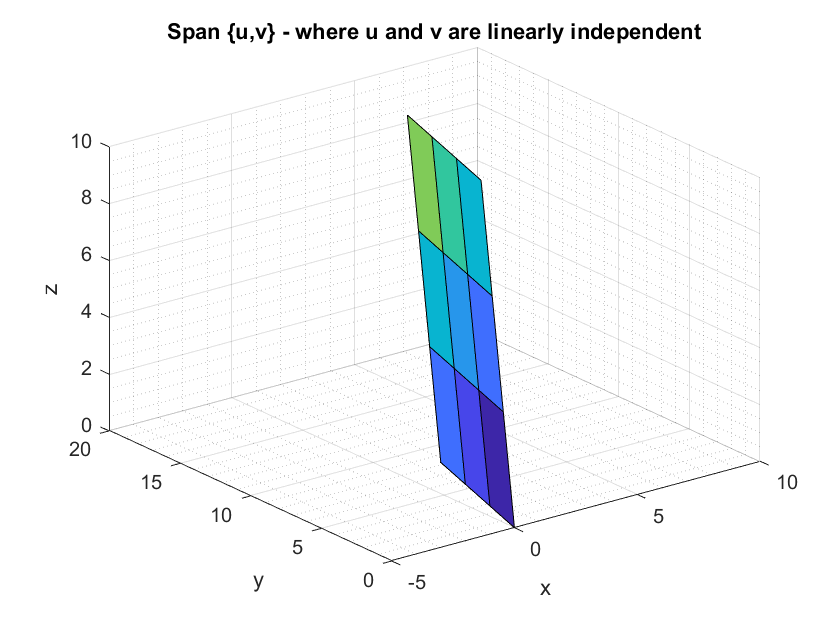

% Define two vectors in R^3
u = [3; 6; 2];
v = [-1; 0; 1];

% Define a range of values for the scalars a and b
a = 0:1:3;
b = 0:1:3;

% Create a grid of values for a and b
[A, B] = meshgrid(a, b);

% Compute the linear combinations of u and v for each value of a and b
X = A .* u(1) + B .* v(1);
Y = A .* u(2) + B .* v(2);
Z = A .* u(3) + B .* v(3);

% Plot the span of u and v as a surface in R^3
surf(X, Y, Z);
grid on; grid minor;
title("Span \{u,v\} - where u and v are linearly independent")
xlabel('x');
ylabel('y');
zlabel('z');

## u and v are linearly dependent

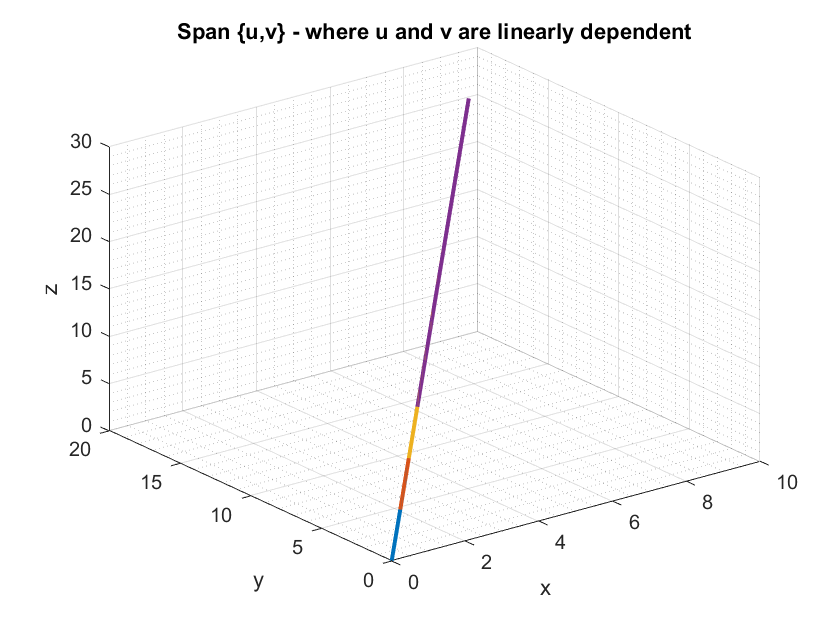

% Define two linearly dependent vectors in R^3
u = [1; 2; 3];
v = [2; 4; 6];

% Define a range of values for the scalar a
a = 0:1:3;

% Create a grid of values for a
[A, B] = meshgrid(a, a);

% Compute the linear combinations of u and v for each value of a
X = A .* u(1) + B .* v(1);
Y = A .* u(2) + B .* v(2);
Z = A .* u(3) + B .* v(3);

% Plot the span of u and v as a line in R^3
plot3(X, Y, Z, "LineWidth", 2);
grid on; grid minor;
xlabel('x');
ylabel('y');
zlabel('z');
title('Span \{u,v\} - where u and v are linearly dependent');


$$\[
f(x) =
\begin{cases}
\frac{1}{4}x, & \text{if } 0\leq  x\leq 2 \\
\frac{x}{4}, &\text{if } 2\leq  x\leq 4 \\
0, & \text{otherwise}
\end{cases}
\]
$$


where $f(x)$ is a probability density function

syms x
f(x) = piecewise((0 <= x) & (x <= 2), (1/4)*x, (2 <= x) & (x <= 4), 1-(1/4)*x,0)

$$f(x) = \left\{ \begin{array}{cl} \frac{x}{4} & \text{ if }x\in \left[0,2\right]\\ 1-\frac{x}{4} & \text{ if }x\in \left[2,4\right]\\ 0 & \mathrm{otherwise} \end{array}\right.$$

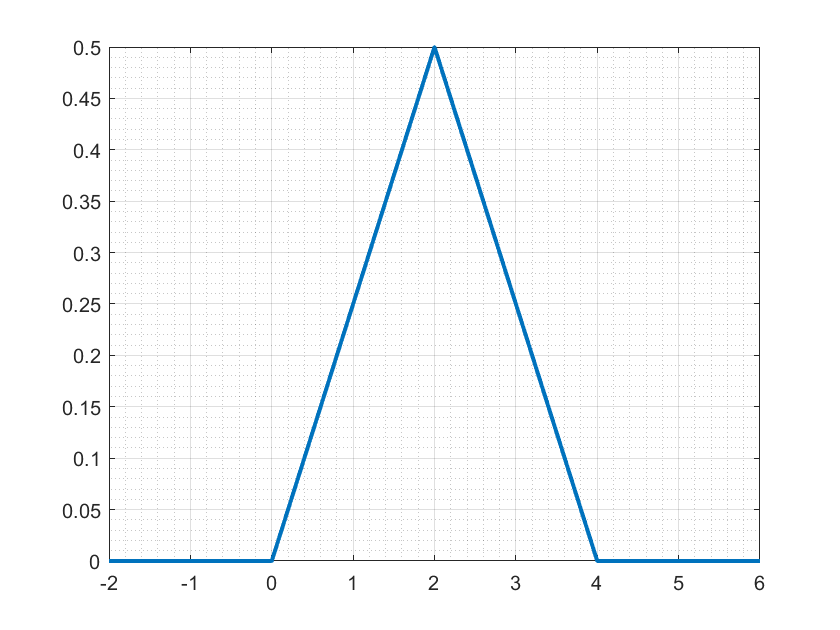

fplot(f,[-2 6], "LineWidth",2);
grid minor; grid on;